### Ładowanie pliku obrazu

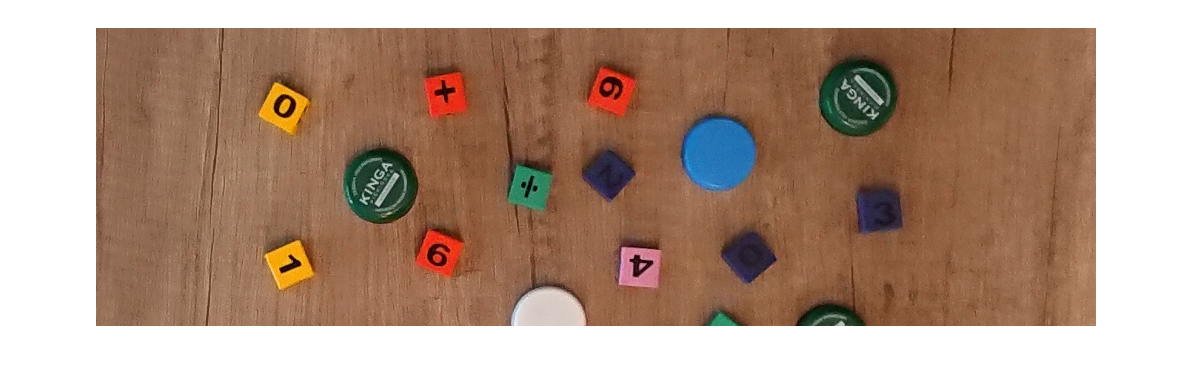

RGB = imread('sample.jpg');
imshow(RGB);

### Separacja kanału barwy

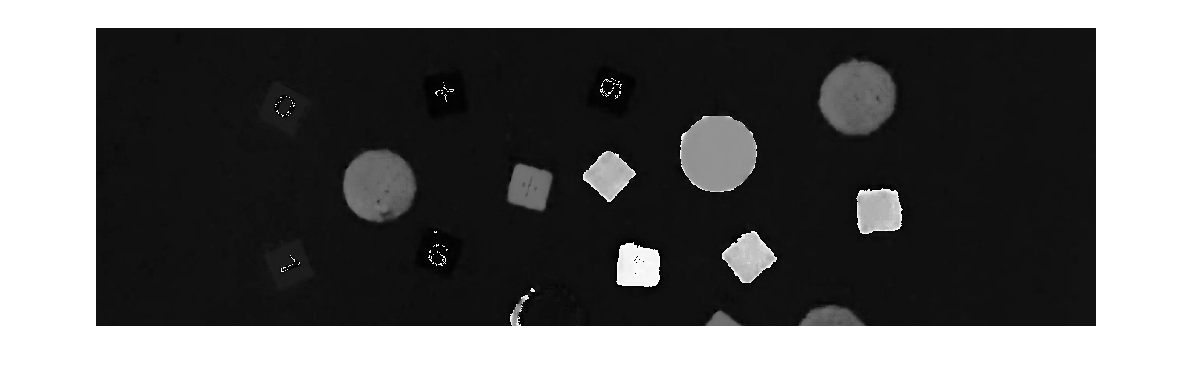

HSV = rgb2hsv(RGB);
H = HSV(:,:,1);
imshow(H);

### Wizualizacja kanału barwy

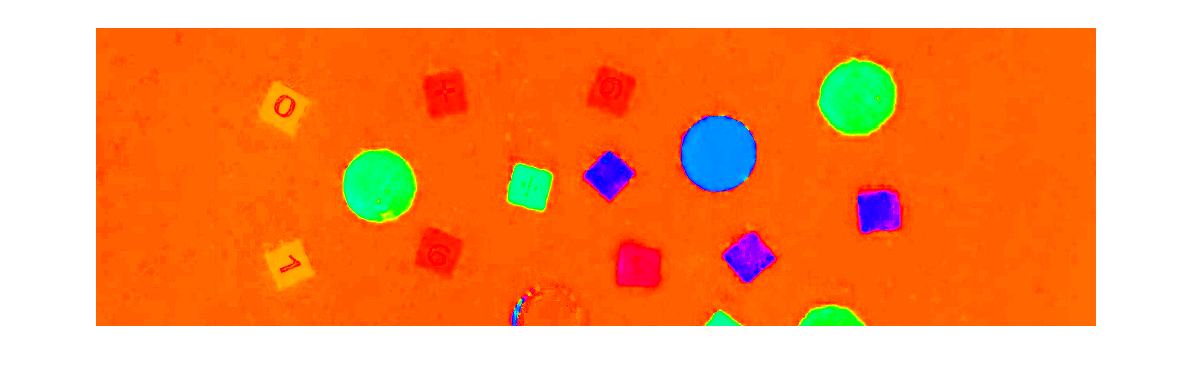

imshow(H);
colormap('hsv');

### Progowanie kolorów

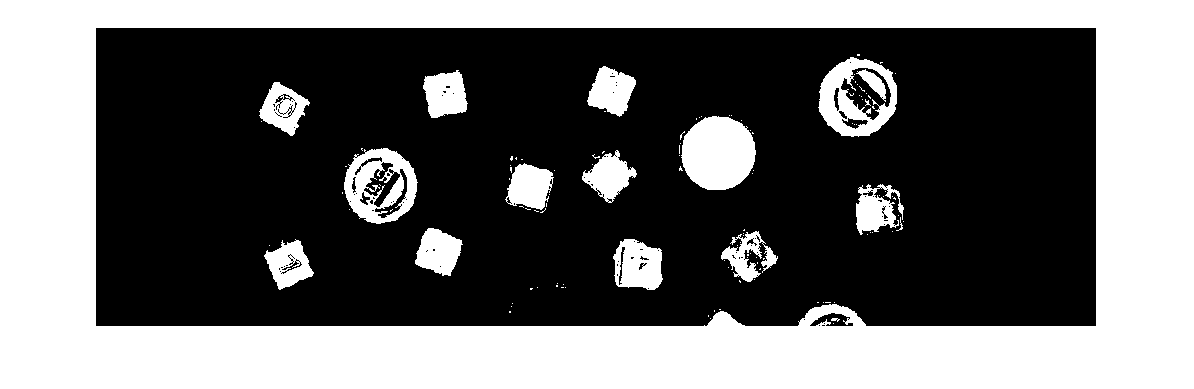

% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.096;
channel1Max = 0.034;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.315;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

imshow(BW);

### Poprawa maski

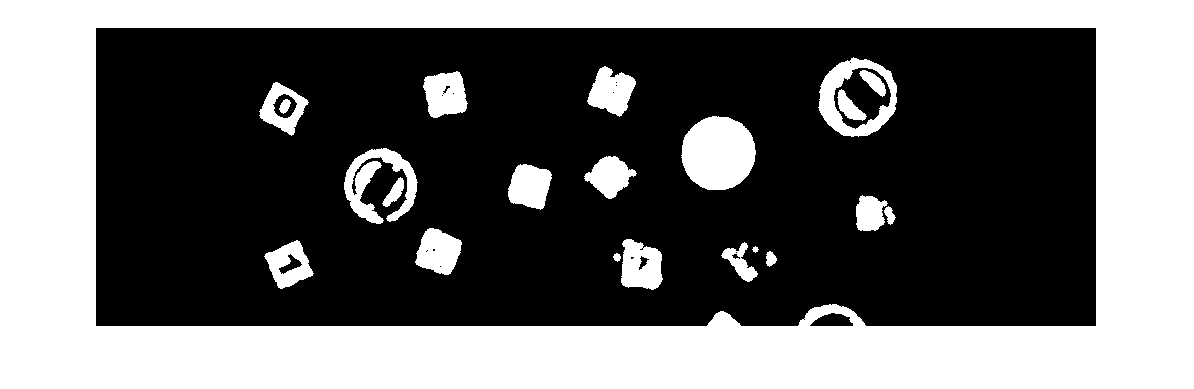

% Open mask with disk
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);
imshow(BW);

### Segmentacja na regiony

props = regionprops(BW, {'Area', 'Eccentricity', 'EquivDiameter', 'BoundingBox', 'PixelIdxList', 'Centroid'});

### Filtracja regionów po rozmiarze i odczytanie średniej barwy

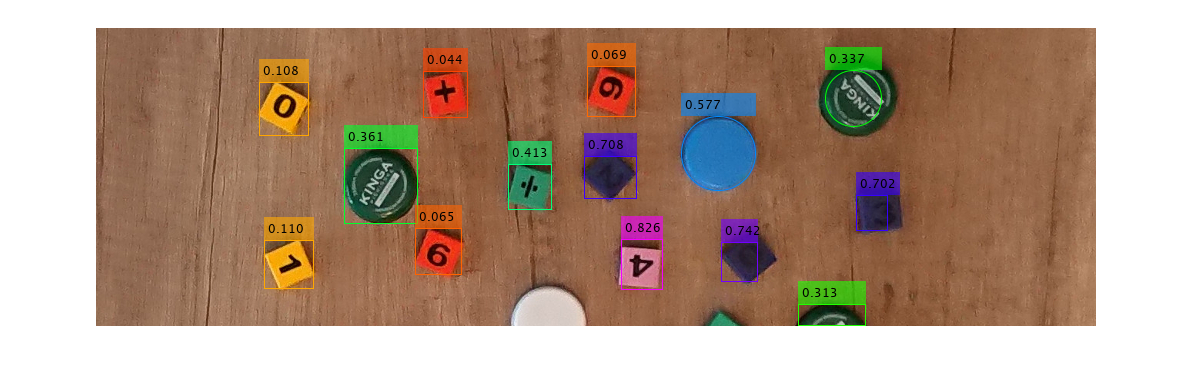

out = RGB;
for i=1:size(properties, 1)
    if props(i).Area > 500
        avg_h = mean(H(props(i).PixelIdxList));
        label = sprintf("%.3f", avg_h);
        color = hsv2rgb([avg_h, 1, 1]) * 255;
        if props(i).Eccentricity < 0.2
            shape = "circle";
            pos = [props(i).Centroid, props(i).EquivDiameter/2];
        else
            shape = "rectangle";
            pos = props(i).BoundingBox;
        end
        out = insertObjectAnnotation(out, shape, pos, label, "Color", color) ;
    end
end
imshow(out);